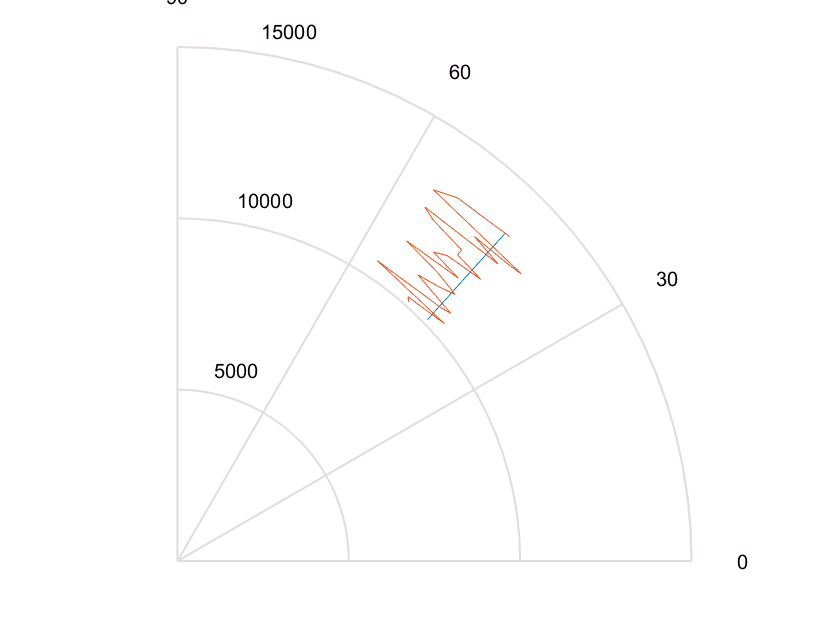

clc; clear; close all; 
addpath('functions/');

n = 26;

X = zeros(2,n);

x0 = 13500/(2)^(0.5);
X(:,1) = [x0; x0];

V = [-50; -45];
t = 2;

sigmaB = 0.09;
sigmaD = 30;
BNoise = normrnd(0,sigmaB,1,n);
DNoise = normrnd(0,sigmaD,1,n);

for i=2:n
    X(:, i) = X(:,i-1) + V*t;   
end

D = dist([0;0],X);  
B = atan( X(1,:) ./ X(2,:) );
D = D(1,:);
Dm = D + DNoise;
Bm = B + BNoise;


polar(B,D);hold on;
polar(Bm,Dm);
axis([0 inf 0 inf]);